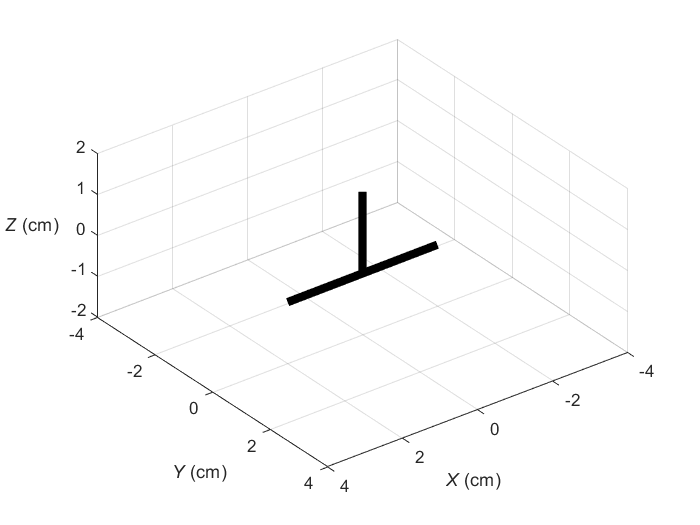

clear;
load BFCS_E1E2E3.mat
e1=E1;
e2=E2;
e3=E3;

LAG = 0.5;     	%  cm
LBC = 4;        %  cm
LAD = 2;        %  cm

%  The T-handle's orientation varies over time according to the evolution
%  of the principal corotational basis {e1,e2,e3}.  Solve for how
%  {e1,e2,e3} vary over time.  Also, keep track of points on the T-handle
%  that are needed to animate its motion:
dt = 0.0005;
xA = zeros(length(tsim),1);
yA = zeros(length(tsim),1);
zA = zeros(length(tsim),1);
xB = zeros(length(tsim),1);
yB = zeros(length(tsim),1);
zB = zeros(length(tsim),1);
xC = zeros(length(tsim),1);
yC = zeros(length(tsim),1);
zC = zeros(length(tsim),1);
xD = zeros(length(tsim),1);
yD = zeros(length(tsim),1);
zD = zeros(length(tsim),1);

for k = 1:length(tsim)
    xA(k,1) = -LAG*e2(1,k);                         %  cm
    yA(k,1) = -LAG*e2(2,k);                         %  cm                        
    zA(k,1) = -LAG*e2(3,k);                         %  cm 
    xB(k,1) = xA(k) + LBC/2*e1(1,k);                %  cm
    yB(k,1) = yA(k) + LBC/2*e1(2,k);                %  cm                                
    zB(k,1) = zA(k) + LBC/2*e1(3,k);                %  cm
    xC(k,1) = xA(k) - LBC/2*e1(1,k);                %  cm
    yC(k,1) = yA(k) - LBC/2*e1(2,k);                %  cm                                
    zC(k,1) = zA(k) - LBC/2*e1(3,k);                %  cm 
    xD(k,1) = xA(k) + LAD*e2(1,k);                  %  cm 
    yD(k,1) = yA(k) + LAD*e2(2,k);                  %  cm                                 
    zD(k,1) = zA(k) + LAD*e2(3,k);                  %  cm 
end

%  Set up the figure window:

figure
set(gcf, 'color', 'w')
plot3(0, 0, 0);
xlabel('\itX\rm (cm)')
set(gca, 'xdir', 'reverse')
ylabel('\itY\rm (cm)')
set(gca, 'ydir', 'reverse')
zlabel('\itZ\rm (cm)            ', 'rotation', 0)
axis equal
xlim(LBC*[-1, 1]);
ylim(LBC*[-1, 1]);
zlim(LAD*[-1, 1]);
grid on

%  Draw the T-handle:

AD = line('xdata', [xA(1), xD(1)], 'ydata', [yA(1), yD(1)], 'zdata', [zA(1), zD(1)], 'color', 'k', 'linewidth', 5);
BC = line('xdata', [xB(1), xC(1)], 'ydata', [yB(1), yC(1)], 'zdata', [zB(1), zC(1)], 'color', 'k', 'linewidth', 5);

%  Animate the T-handle's motion by updating the figure with its current 
%  orientation:
pause


animation = VideoWriter('t-handle.avi');
animation.FrameRate = 1/dt;       

for k = 1:length(psi)
    set(AD, 'xdata', [xA(k), xD(k)], 'ydata', [yA(k), yD(k)], 'zdata', [zA(k), zD(k)]);
    set(BC, 'xdata', [xB(k), xC(k)], 'ydata', [yB(k), yC(k)], 'zdata', [zB(k), zC(k)]);
    drawnow
    writeVideo(animation, getframe(gcf));
end
